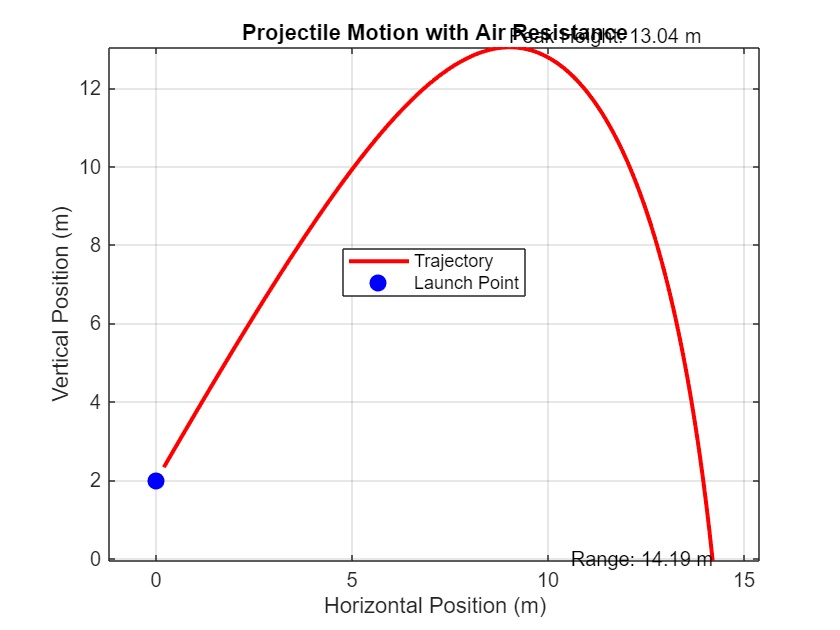

% Projectile Motion with Air Resistance
clc;
clear;
close all;

% Parameters
m = 1;                % Mass of the projectile (kg)
g = 9.81;             % Acceleration due to gravity (m/s^2)
b = 0.1;              % Air resistance coefficient (kg/m)
initial_height = 2;   % Initial height (m)
initial_velocity = 40;% Initial velocity (m/s)
angle_deg = 60;       % Launch angle in degrees

% Time parameters
dt = 0.01;            % Time step (s)
t_max = 10;           % Maximum simulation time (s)
num_steps = t_max / dt;

% Initial conditions
theta = deg2rad(angle_deg); % Convert angle to radians
vx = initial_velocity * cos(theta); % Initial horizontal velocity (m/s)
vy = initial_velocity * sin(theta); % Initial vertical velocity (m/s)
x = 0;                % Initial horizontal position (m)
y = initial_height;   % Initial vertical position (m)

% Preallocate arrays for performance
time = zeros(1, num_steps);
x_pos = zeros(1, num_steps);
y_pos = zeros(1, num_steps);
vx_arr = zeros(1, num_steps);
vy_arr = zeros(1, num_steps);

% Initialize variables
x_pos(1) = x;
y_pos(1) = y;
vx_arr(1) = vx;
vy_arr(1) = vy;

% Simulation loop
for i = 1:num_steps
    % Current velocity magnitude
    v = sqrt(vx^2 + vy^2);
    
    % Forces
    Fx = -b * v * vx; % Air resistance in the x-direction
    Fy = -b * v * vy - m * g; % Air resistance and gravity in the y-direction
    
    % Accelerations
    ax = Fx / m;
    ay = Fy / m;
    
    % Update velocities
    vx = vx + ax * dt;
    vy = vy + ay * dt;
    
    % Update positions
    x = x + vx * dt;
    y = y + vy * dt;
    
    % Store results
    time(i) = i * dt;
    x_pos(i) = x;
    y_pos(i) = y;
    vx_arr(i) = vx;
    vy_arr(i) = vy;
    
    % Stop the simulation if the projectile hits the ground
    if y <= 0
        break;
    end
end

% Truncate arrays to actual simulation length
time = time(1:i);
x_pos = x_pos(1:i);
y_pos = y_pos(1:i);

% Plot the trajectory
figure;
plot(x_pos, y_pos, 'r-', 'LineWidth', 2);
grid on;
axis equal;
xlabel('Horizontal Position (m)');
ylabel('Vertical Position (m)');
title('Projectile Motion with Air Resistance');
hold on;

% Plot initial height
plot(0, initial_height, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'blue');

% Annotate max height and range
[max_y, max_idx] = max(y_pos); % Max height
max_x_at_peak = x_pos(max_idx); % X at max height
final_x = x_pos(end); % Horizontal range

% Add text annotations
text(max_x_at_peak, max_y, sprintf('Peak Height: %.2f m', max_y), 'VerticalAlignment', 'bottom');
text(final_x, 0, sprintf('Range: %.2f m', final_x), 'HorizontalAlignment', 'right');

% Add trajectory legend
legend('Trajectory', 'Launch Point', 'Location', 'Best');